 clear; close all;

## **System-Level Design**

===========================================================

SNR required for given ENOB

% parameter
ENOB = 12;

% calculation
SNR_dB = ENOB * 6.02 + 1.76;

% results
SNR_dB

SNR_dB = 74

OSR required given SNR

% parameter
vpp_in_diff = 0.9*1.8;
vdd = 1.8;          
SNR_dB;             % from prev section

% Time domain approach
% compares signal power level with noise power level using magnitude of
% error in time domain, includes digital filters of order 2
u = vpp_in_diff/vdd

u = 0.9000

u_dBFS = 20*log10(u);
OSR_1 = 0.5*(1 + sqrt(1 + 4*(2/u*10^(SNR_dB/20))));

% Frequency domain approach
% calculates in-band quantization noise using NTF of MOD2, does not include
% filters
OSR_2 = (10^(SNR_dB/10)*(2*pi^4)/(15))^0.2;

% results
u_dBFS

u_dBFS = -0.9151

OSR_1

OSR_1 = 106.0355

OSR_2

OSR_2 = 50.4322

SQNR vs Input Amplitude

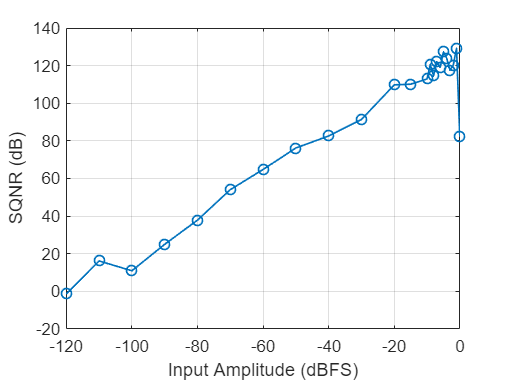

% Schreier book
% SQNR vs Input Amplitude Theoretical
order = 2;
OSR = 512;
M = 1;
% For NTF: max out-of-band gain < 2 for stable mod with binary quantizer
% Tradeoff SNR with stability
ntf = synthesizeNTF(order,OSR,0,2,0);
% Plot the SQNR vs. amplitude curve
[sqnr, amp] = simulateSNR(ntf,OSR,[],[],M+1);
figure;
plot(amp,sqnr,'-o','Linewidth',1);
xlabel("Input Amplitude (dBFS)")
ylabel("SQNR (dB)")
grid;

DSM Implementation: ABCD Matrix

form = 'CIFB';
swing = 0.5; %Amplifier output swing, Vp
umax = 0.9; %Scale system for inputs up to 0.9 of full-scale
[a,g,b,c] = realizeNTF(ntf,form);
b(3:end) = 0;
ABCD = stuffABCD(a,g,b,c,form);
ABCD = scaleABCD(ABCD,M+1,[],swing,[],umax);
[a,g,b,c] = mapABCD(ABCD,form)

a =     0.3597    0.1252


g = 0

b =     0.3597    0.1252         0


c =     0.1329    9.8767


a1 = a(1);
a2 = a(2);
b1 = b(1);
b2 = b(2);
c1 = c(1);
c2 = 1;

DSM **Simulink** System Simulation: PSD

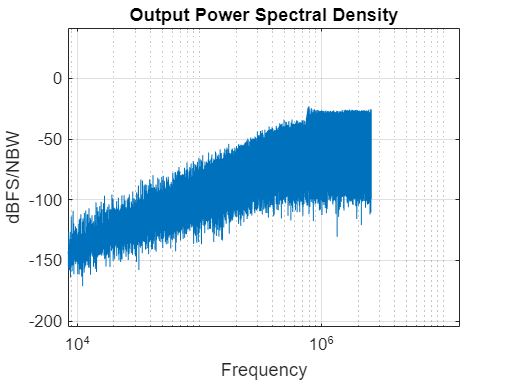

SNR_sl = 117.5463

neg_THD_sl = -95.3756

ENOB_sl = 19.2336

% control parameters
rounding = false;
plot_on = true;
sweep = false;

f = 2.5e3;  % frequency of input
f_bw = 5e3;  % signal bandwidth
OSR = 512;
f_sampling = 2*f_bw*OSR;  % oversampling frequency

vref_p = vdd/2;
vref_n = -vdd/2;

% simulation time in seconds
% smaller -> less resolution faster simulation
t_sim = 0.1;

vin = 0.7 * vdd/2;

if(~rounding)
    a1 = a(1);
    a2 = a(2);
    b1 = b(1);
    b2 = b(2);
    c1 = c(1);
    c2 = 1;  % unnecessary since only sign is looked at
else
    a1 = 0.4;
    a2 = 0.2;
    b1 = 0.4;
    b2 = 0.2;
    c1 = 0.2;
    c2 = 1;
end

if(sweep)
    SNR_list = [];
    neg_THD_list = [];
    ENOB_list = [];
    for vin = [0.5:0.05:0.9]*vdd/2
        % call simulink for psd simulation
        out = sim('dsm_o2_scaling_system.slx');
        N = length(out.simout.Data);
        fft_bins = ceil(N/(2*OSR));
        % note on amplitude scaling factors:
        %   - Hanning window: amplitude correction factor of 2
        %   - Single-side spectra: amplitude correction factor of 2
        %   - DFT: amplitude correction factor of 1/N. For dBm/Hz, use 1/sqrt(N*f_sampling)
        spec = fft(out.simout.Data'.*ds_hann(N));
        psd_dbfs = 10*log10(abs(spec/(N/4)).^2);
        psd_dbm = 10*log10(4/(f_sampling*sum(ds_hann(N)))*abs(spec).^2/1e-3);  % PSD in dBm/Hz, ref to 1 ohm
        
        % calculate SNR, THD, ENOB
        SNR_sl = calculateSNR(spec(1:fft_bins)/(N/4),f/(f_sampling/N));
        neg_THD_sl = psd_dbfs(f/(f_sampling/N) + 1) - psd_dbfs(3*f/(f_sampling/N) + 1);
        ENOB_sl = (SNR_sl - 1.76)/6.02;
        
        SNR_list = [SNR_list SNR_sl];
        neg_THD_list = [neg_THD_list neg_THD_sl];
        ENOB_list = [ENOB_list ENOB_sl];
    end
    
    % outputs
    figure;
    vin = [0.5:0.05:0.9]*vdd/2;
    hold on;
    plot(vin/(vdd/2), SNR_list, 'b-o')
    plot(vin/(vdd/2), neg_THD_list, 'g-o')
    xlabel("vin (%FS)")
    ylabel("dBFS")
    grid;
    legend("SNR","-THD")

    SNR_list
    neg_THD_list
    ENOB_list

else    
    % call simulink for psd simulation
    out = sim('dsm_o2_scaling_system.slx');
    N = length(out.simout.Data);
    fft_bins = ceil(N/(2*OSR));
    % note on amplitude scaling factors:
    %   - Hanning window: amplitude correction factor of 2
    %   - Single-side spectra: amplitude correction factor of 2
    %   - DFT: amplitude correction factor of 1/N. For dBm/Hz, use 1/sqrt(N*f_sampling)
    spec = fft(out.simout.Data'.*ds_hann(N));
    psd_dbfs = 10*log10(abs(spec/(N/4)).^2);
    psd_dbm = 10*log10(4/(f_sampling*sum(ds_hann(N)))*abs(spec).^2/1e-3);  % PSD in dBm/Hz, ref to 1 ohm
    
    % plot psd
    if(plot_on)
        figure;
        semilogx(linspace(0, f_sampling/2, N/2+1), psd_dbfs(1:N/2+1));  
        title("Output Power Spectral Density");
        axis([1e4 f_sampling/2 -180 5])
        xlabel("Frequency");
        ylabel("dBFS/NBW"); 
        grid;
    end
    
    % calculate SNR, THD, ENOB
    SNR_sl = calculateSNR(spec(1:fft_bins)/(N/4),f/(f_sampling/N))
    neg_THD_sl = -psd_dbfs(f/(f_sampling/N) + 1) + psd_dbfs(3*f/(f_sampling/N) + 1)
    ENOB_sl = (SNR_sl - 1.76)/6.02
end

DS **Toolbox** DSM Simulation

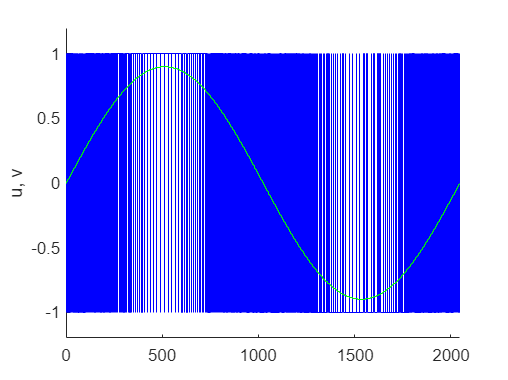

plot_on = true;

OSR = 512;
f = 2.5e3;
f_bw = 5e3;
order = 2;
f_sampling = 2*f_bw*OSR;
fft_bins = ceil(f_sampling/(2*OSR));
u = 0.9*sin(2*pi*f/f_sampling*[0:f_sampling-1]);

ntf = synthesizeNTF(order,OSR,0,2,0);
v = simulateDSM(u,ntf);

% time domain plot
if(plot_on)
    figure;
    t = 0:f_sampling/f;
    hold on;
    stairs(t,v(t+1),'b');
    stairs(t,u(t+1),'g');
    axis([0 f_sampling/f -1.2 1.2]);
    ylabel('u, v');
end

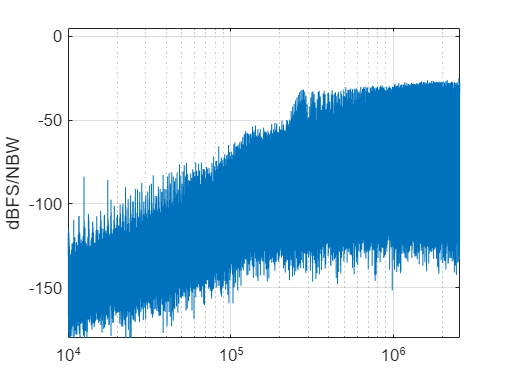


spec = fft(v.*ds_hann(f_sampling))/(f_sampling/4);
SNR_tb = calculateSNR(spec(1:fft_bins),f);

% frequency domain plot
if(plot_on)
    figure;
    semilogx(linspace(0,f_sampling/2,f_sampling/2+1), dbv(spec(1:f_sampling/2+1)));
    axis([1e4 f_sampling/2 -180 5])
    grid on;
    ylabel('dBFS/NBW')
end


SNR_tb

SNR_tb = 118.1586

ENOB_tb = (SNR_tb - 1.76)/6.02

ENOB_tb = 19.3353

## Circuit-Level Design

===========================================================

Input Sampling Cap vs OSR

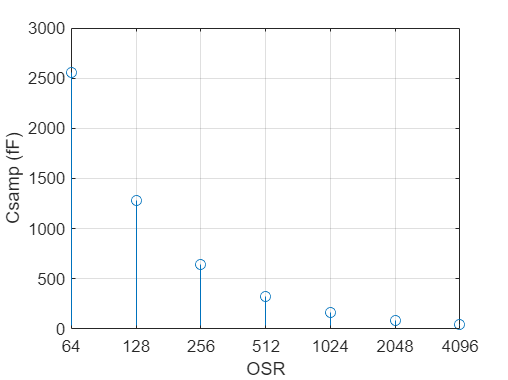

vin_pp = 0.5*vdd;  % higher = less OSR
SNR = 90;  % target SNR
k = 1.3806e-23;
T = 300;

% assume total input-referred noise 4kT/C
OSR = [64,128,256,512,1024,2048,4096];
% stage 1 Csamp
C1 = (4*k*T)./(OSR*0.5*(vin_pp/2)^2*10^(-SNR/10));

figure;
stem(log2(OSR), C1/1e-15)
xlabel("OSR")
xticklabels(OSR)
ylabel("Csamp (fF)")
grid;


C1 = C1(4);

% Coefficients include DAC ref voltage since v is unitless
% but the difference equations are not  
C2 = C1/b1*vdd;
C4 = 10e-15;  % min size cap 
C5 = C4*vdd/a2;
C3 = C5*c1;

fprintf("C1 = %d fF/side",round(C1/1e-15))

C1 = 320 fF/side

fprintf("C2 = %d fF/side",round(C2/1e-15))

C2 = 1599 fF/side

fprintf("C3 = %d fF/side",round(C3/1e-15))

C3 = 19 fF/side

fprintf("C4 = %d fF/side",round(C4/1e-15))

C4 = 10 fF/side

fprintf("C5 = %d fF/side",round(C5/1e-15))

C5 = 144 fF/side


% Area estimate of capacitors
C_tot = 2*(C1 + C2 + C3 + C4 + C5);
area = C_tot/2e-15  % in um2

area = 2.0918e+03

area_factor = area/(10e6)

area_factor = 2.0918e-04


% Current needed for slew
f_sampling = 5.12e6;
I = (C1*vdd)/(0.25/f_sampling)

I = 1.1781e-05


% fu for linear settling
f_u = 1/(2*pi)*4*f_sampling*log(1/0.001)

f_u = 2.2516e+07


% stage 1 loading cap
C_L_1 = (C1*C2/(C1+C2)) + C3

C_L_1 = 2.8547e-13


% required gm
g_m = 2*pi*f_u*C_L_1

g_m = 4.0386e-05


% gm id (tentative)
gm_id = g_m/I

gm_id = 3.4280

Digital Filter Simulink Simulation

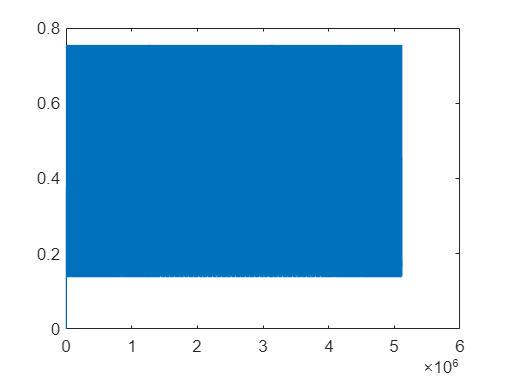

f = 1e3;
vin = 0.7*vdd/2;

out = sim("ds_adc_system.slx");
value = out.simout.Data;

plot(0:1/5.12e6:(5.12e6-1)/5.12e6, value/4096*1.8)